# Greenhouse Control

[⇦ Return to the main menu](matlab:open('../MainMenu.mlx'))

In this script, you will design the control algorithm for a greenhouse. The system relies on a fan blowing fresh air from the outside to cool down the inside of the greenhouse during the warmer months of the year.

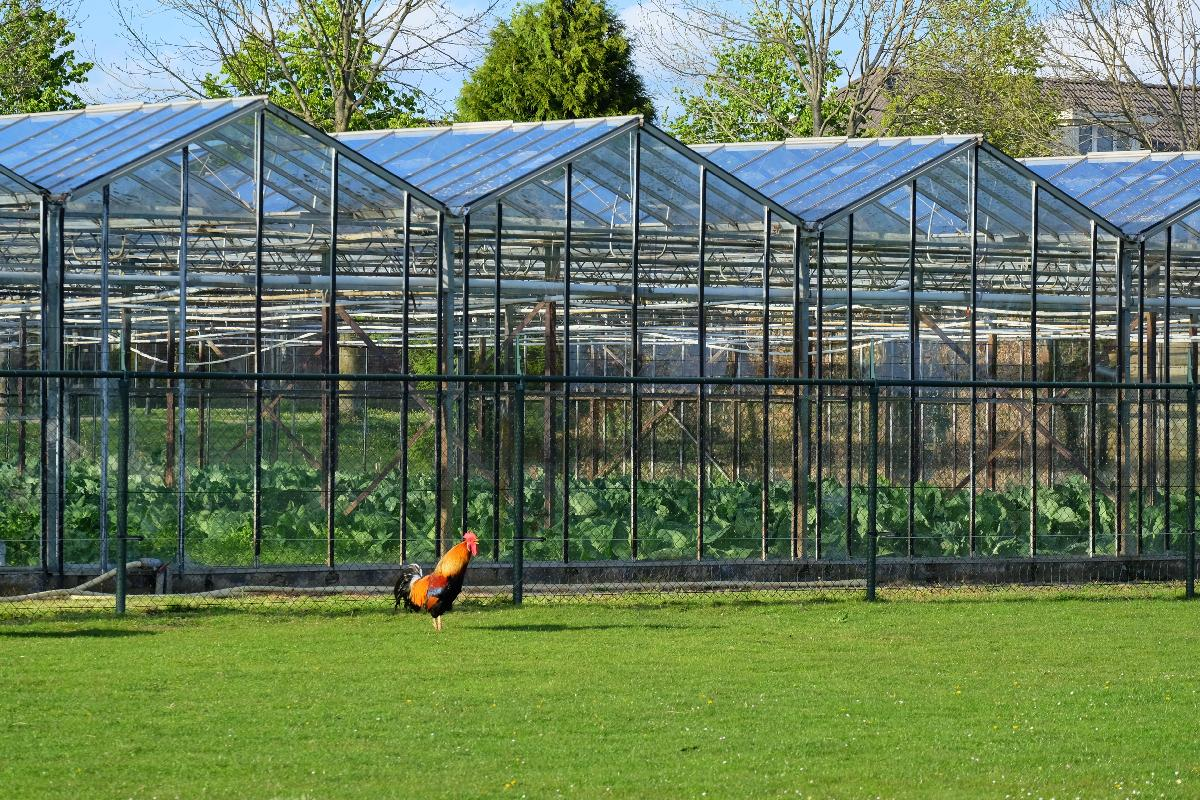

Image retrieved from [Wikimedia](https://commons.wikimedia.org/wiki/File:Greenhouses_in_Bemmel,_Lingewaard.jpg)

**Before you get started:**

This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB Toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code **using the icon  at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2-hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if they run out of order.

The    and   icons refer to two different types of interactive activities that you will find in this script. The    usually indicates an interaction where you will explore the visualization of some concept introduced in this script. The  interactions are designed to challenge your understanding of those concepts and may be used for grading and completion checks by your professor.

Additional 

## Introduction

You local florist is having trouble with their flowers dying due to temperature and humidity conditions in their greenhouse. With your new knowledge of Arduino and MATLAB, you have been hired to help them implement a control system to monitor the temperature and humidity and help regulate it with a fan.

Before beginning this module, please ensure that you have downloaded the following support packages:

[Simulink Arduino DHT Sensor](https://www.mathworks.com/add-ons/62372d32-0e06-4c12-94b5-c1592ca9c6cb/?s_tid=srchtitle)

## Constructing the Circuit

To help the florist, we will need three components other than our Arduino:

- An Arduino Board

- A DC motor with a fan    

- A DHT11 sensor (humidity and temperature sensor)     

 **Exercise.** Construct the circuit with the two components below:

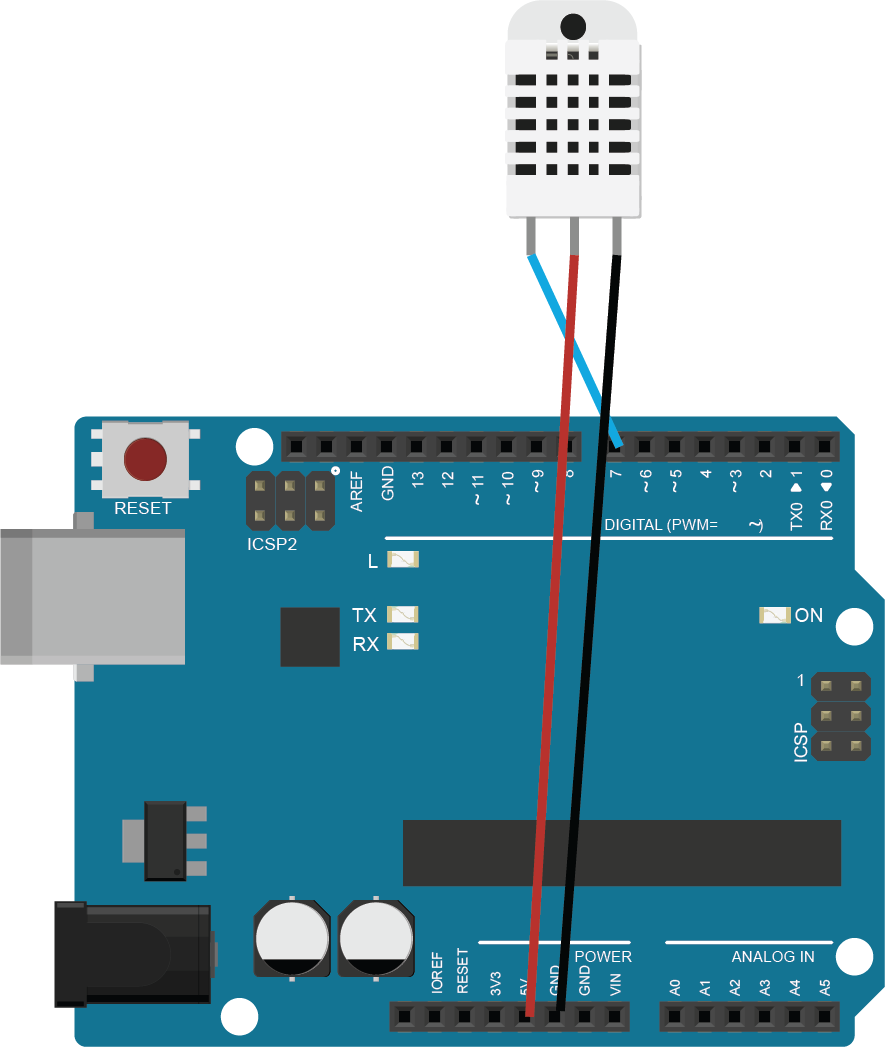

Wiring diagram for DHT sensor - this image was created using [fritzing-parts](https://github.com/fritzing/fritzing-parts/)

  **Try. **Inform the board you are using and the pins used for the DHT sensor.

MyBoard  = "Arduino Uno";
MyDHTPin = "";

 **Exercise.** Wire the DC motor on a PWM pin.

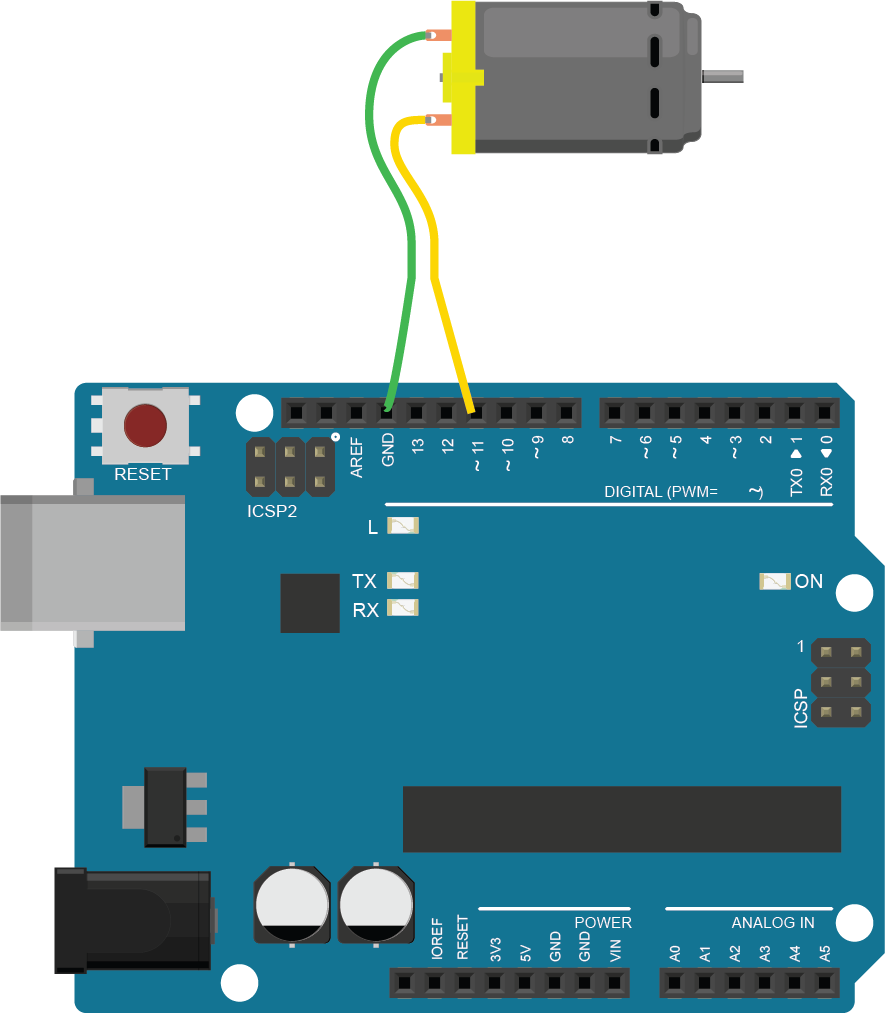

Wiring diagram for DC motor - this image was created using [fritzing-parts](https://github.com/fritzing/fritzing-parts/)

  **Try. **Inform the board you are using and the pins used for the DHT sensor

MyFanPin = "";

 **Reflect.** The digital pins on the Arduino will allow us to send PWM signals to the fan, and read temperature and humidity values from the DHT11 sensor.

## Designing the fan control algorithm

You learned how to create, edit, and simulate models using block diagrams from the Simulink Onramp. Model-based design is powerful because it allows you to edit and simulate systems virtually before deploying them in real life. 

For the below exercises, you will employ Simulink to achieve your final result.

  **Try. **Open the model below.

 
open(fullfile("Models","GreenhouseControl.slx"))

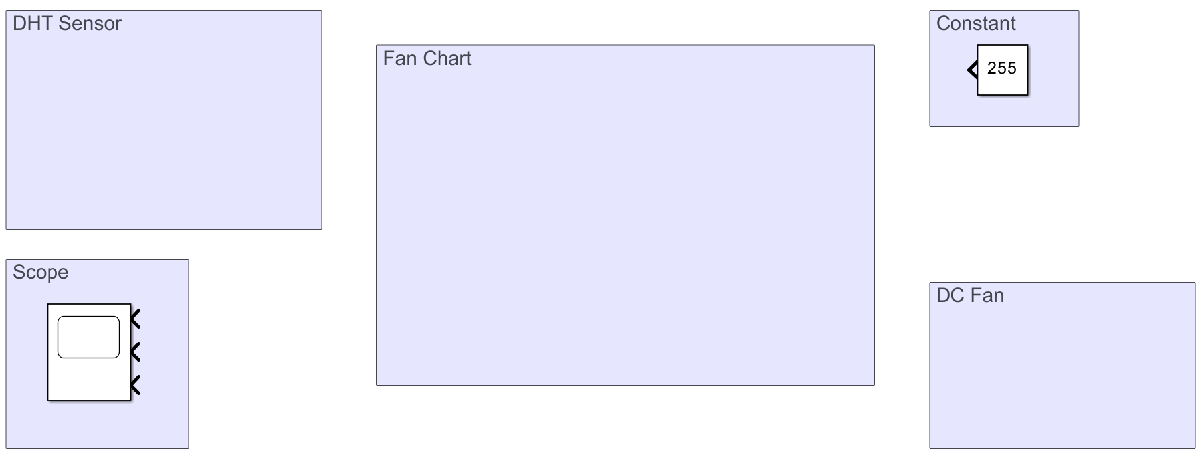

### Connecting the DHT sensor

 **Exercise.** Using the **Library Browser**, search for and add a **DHT** block. Name it **DHT Sensor**, and assign the following values to the DHT block parameters:

**Output in Fahrenheit (F):** Yes

**Pin Number:** your DHT pin

**Sensor Type:** 11

**Sample Time:** 0.5

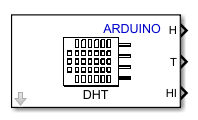

DHT Block from File Exchange

Place this block inside the area labeled **DHT Sensor**, and click the **Check Model **button when completed.

 
CheckDHTBlock(MyDHTPin)

 **Reflect.** This DHT block was created by an external MATLAB user and posted to the File Exchange Website. File exchange allows MATLAB users to share models, libraries, and functionalities with one another that MathWorks have not created

  **Try. **Attach the three outputs of the **DHT** block to the **Scope** block within the model, and click the "Monitor and Tune" button below the **Hardware** tab. 

As soon as the simulation starts running, open the **Scope** block to view the live changes in readings from the DHT sensor.

  **Try. **Blow on the sensor to see the temperature and humidity change.

### **Connecting the DC Fan**

Similar to the Arduino Support Package for MATLAB, the Arduino Support Package for Simulink allows you to create block-based models to run or deploy to, an Arduino microcontroller. You can adjust parameters and test setup behavior in real-time by using interactive blocks like the slider block. 

 **Exercise.** Using the **Library Browser**, search for and add an **Arduino PWM** block. Name it **DC Fan** and assign the following values to the block parameters:

**Pin Number: **your fan pin

**Frequency:** Default

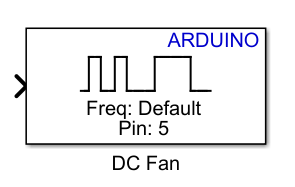

Place this block inside the area labeled **DC Fan**, and click the **Check Model **button when completed.

 
CheckDCFanBlock(MyFanPin)

  **Try. **Attach the output of the **Constant** block to the **DC Fan** block within the model, and click **Monitor and Tune** button below the **Hardware** tab.

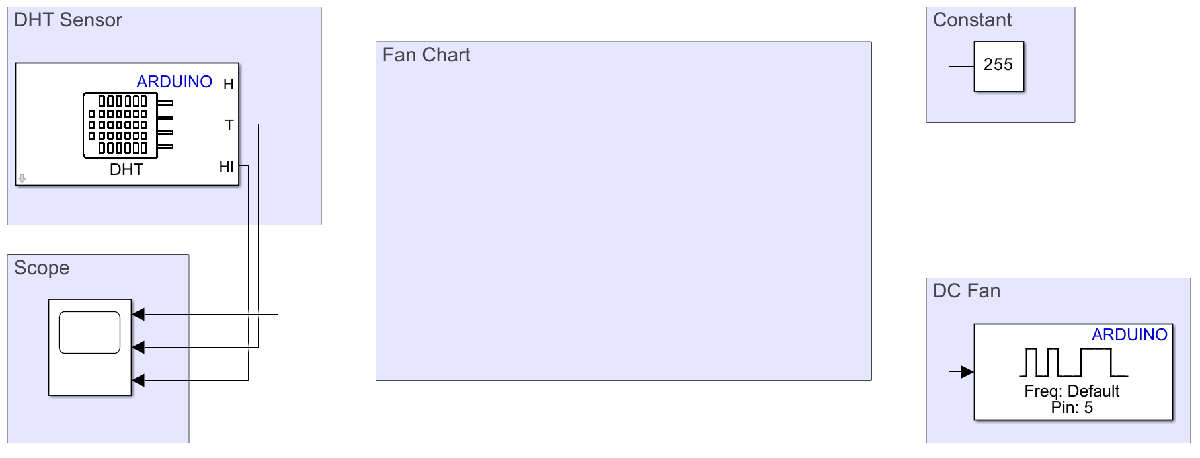

### **Controlling the Fan**

**Stateflow** provides a graphical language that includes state transition diagrams, flow charts, state transition tables, and truth tables. Our application will use Stateflow to determine when the fan should turn on and off.

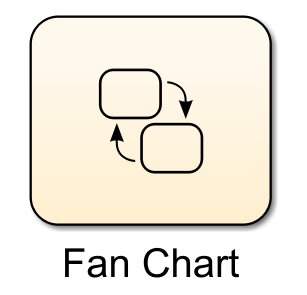

 **Exercise.** Using the **Library Browser**, search for and add a Stateflow **Chart** block.

  CheckInsertChart

The fan control should be based on the temperature, connect

 **Exercise. **Branch the temperature signal from the DHT block (T) into the Stateflow Chart.

  CheckConnectionDHT;

 **Exercise. **Branch the Stateflow outflow signal to the fan block, call this outflow signal **FanSpeed.**

  CheckConnectionPWM

Present three ways to control the fan:

- **Simple Threshold value: **the fan turns on above a certain temperature and turns off below this same temperature

- **Hysteresis: **the fan turns on above a certain temperature and turns off below a lower temperature

- **Hysteresis + Debouncing: **the fan turns on above a certain temperature and turns off after the temperature goes below a lower temperature for some time

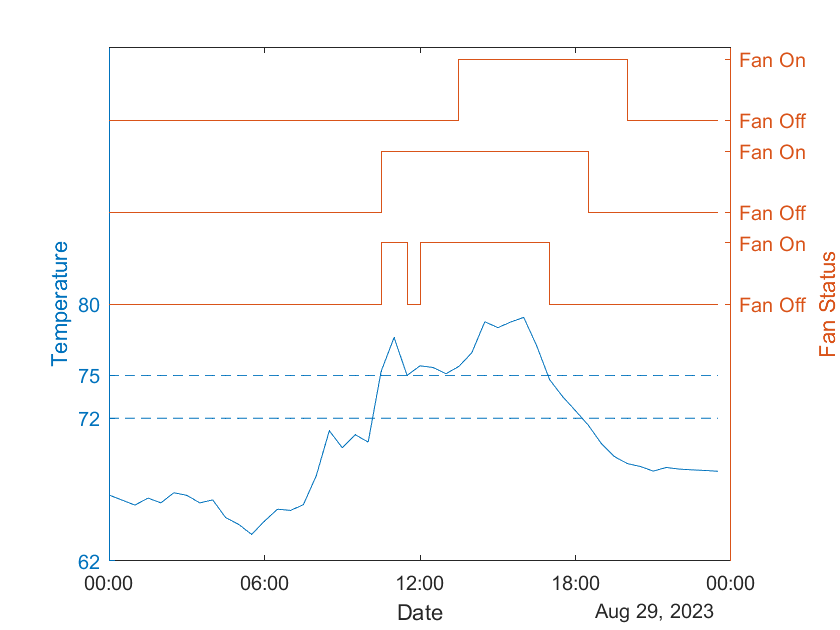

 **Exercise. **Based on the following plot, identify the different control algorithms used.

IdentifyControlSignal("None",...
"None",...
"None");
 

Now that you understand the logic behind the three controls presented, can you identify their corresponding Stateflow implementation?

A)    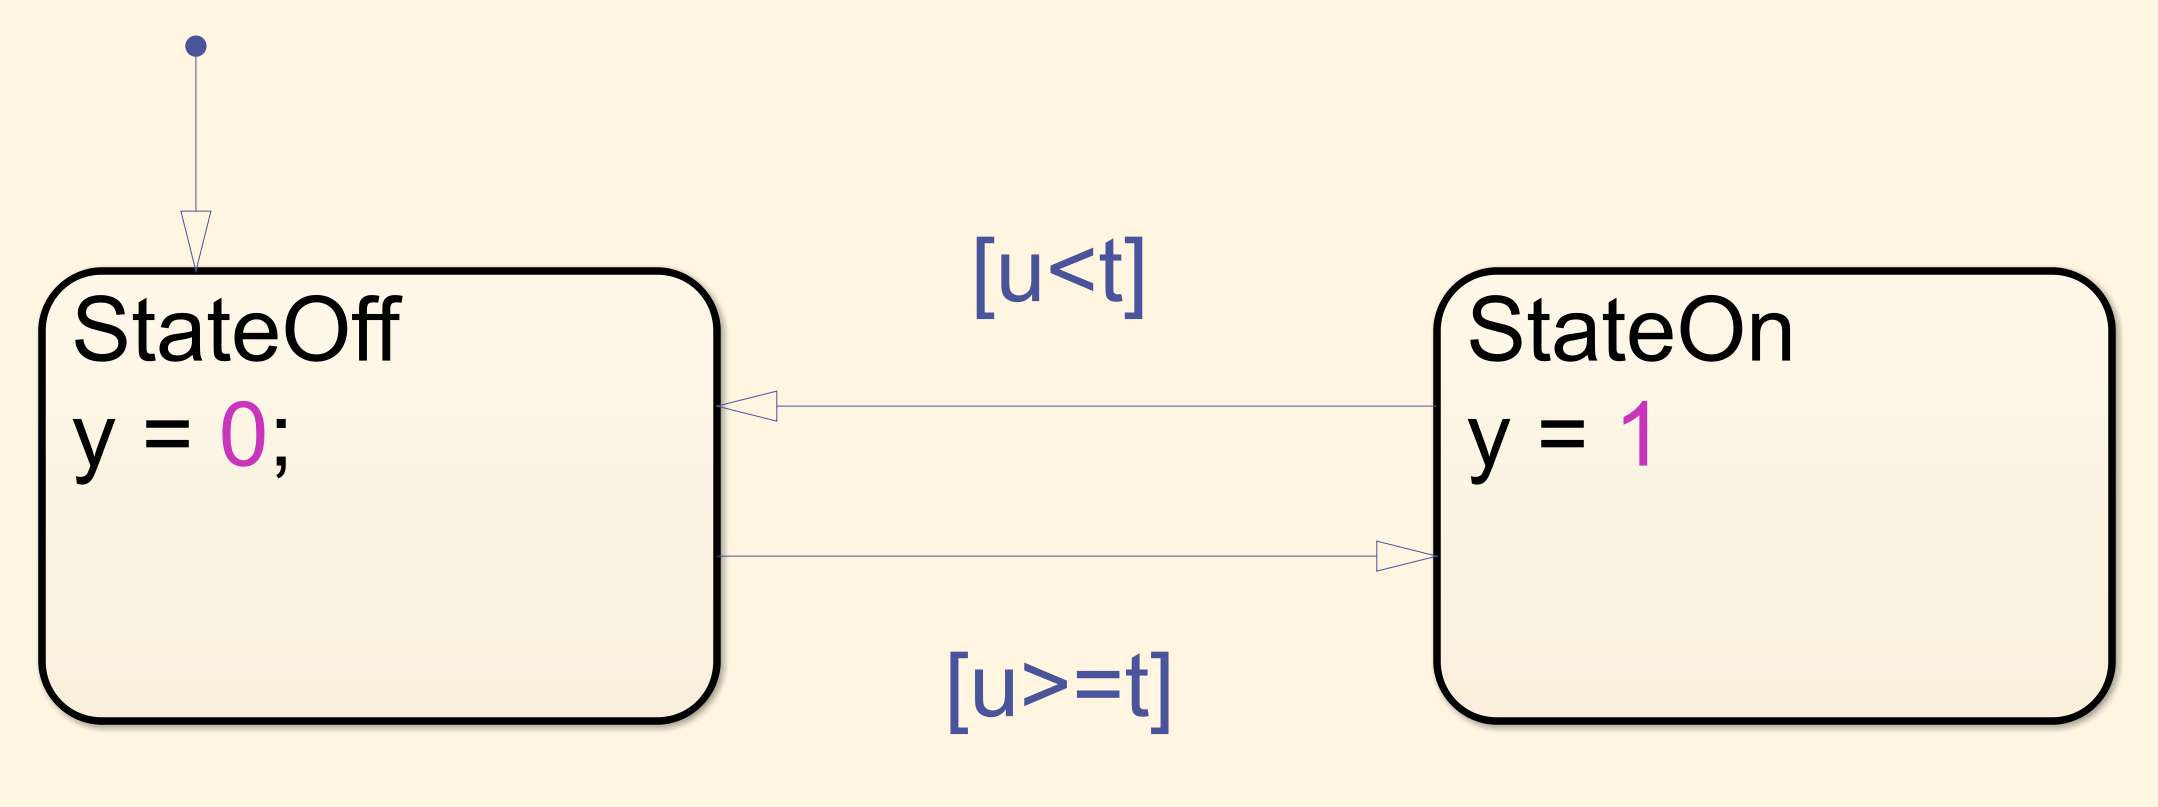

B)    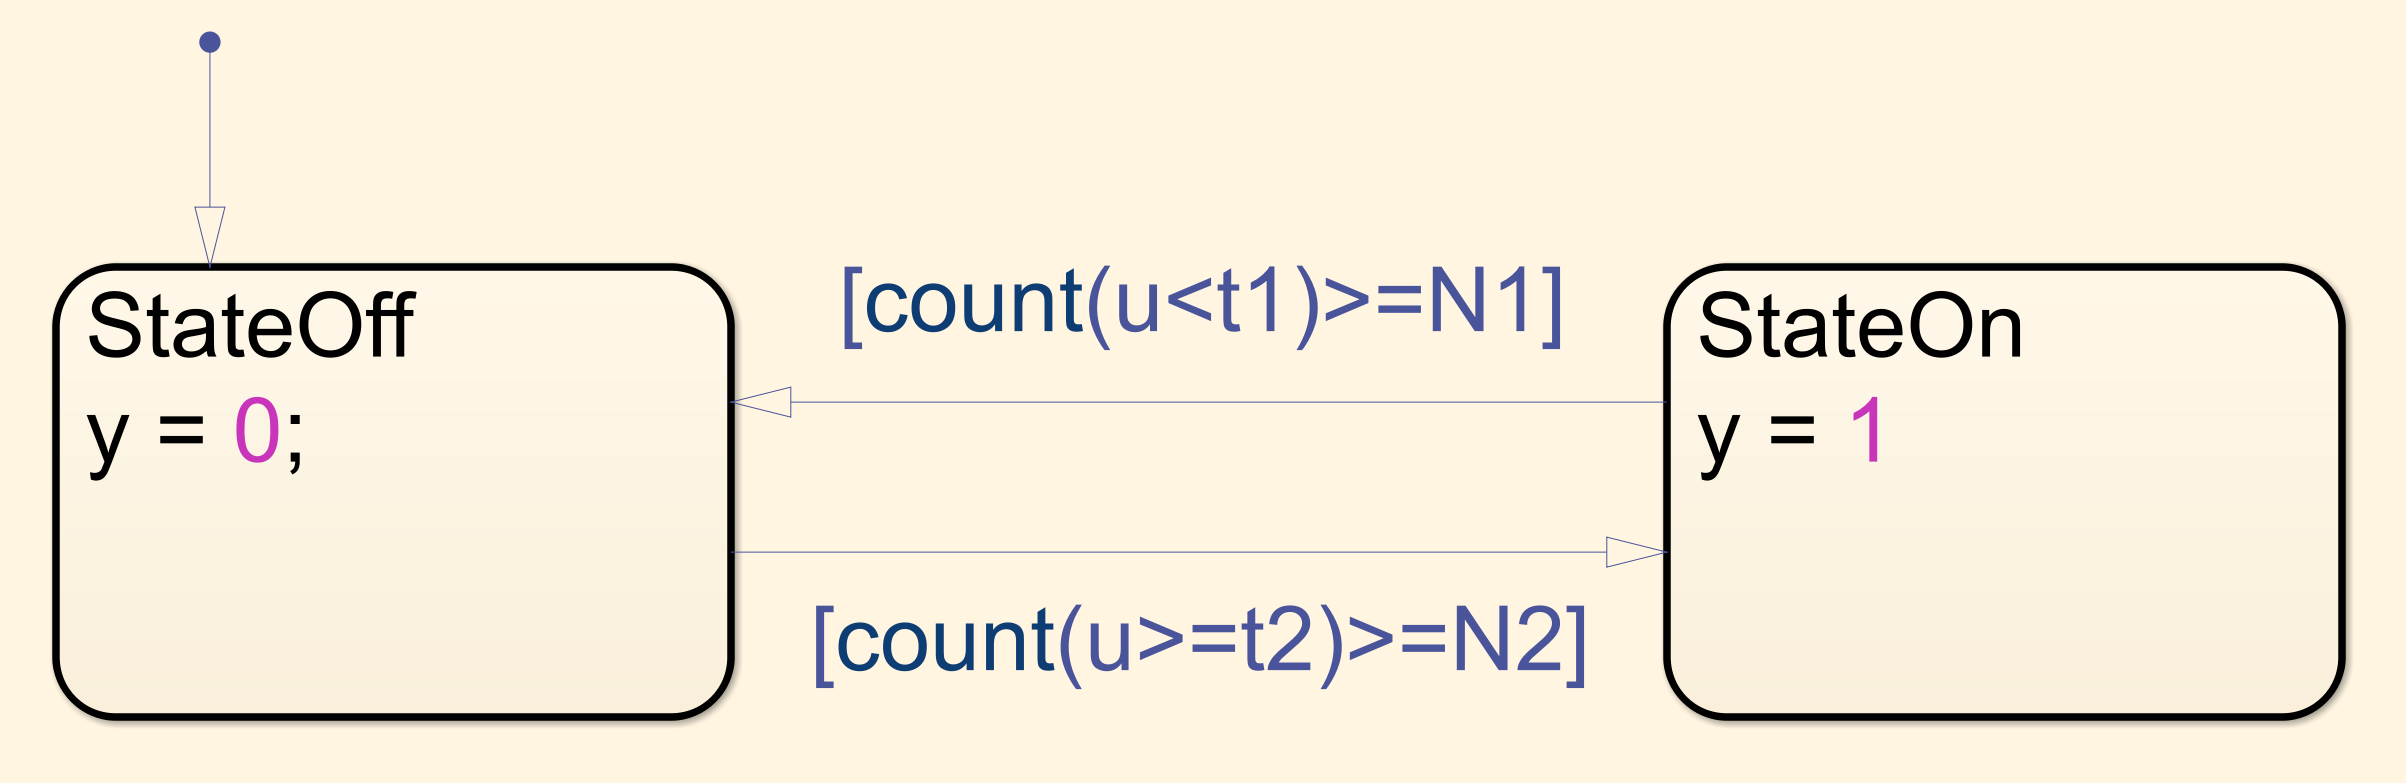

C)    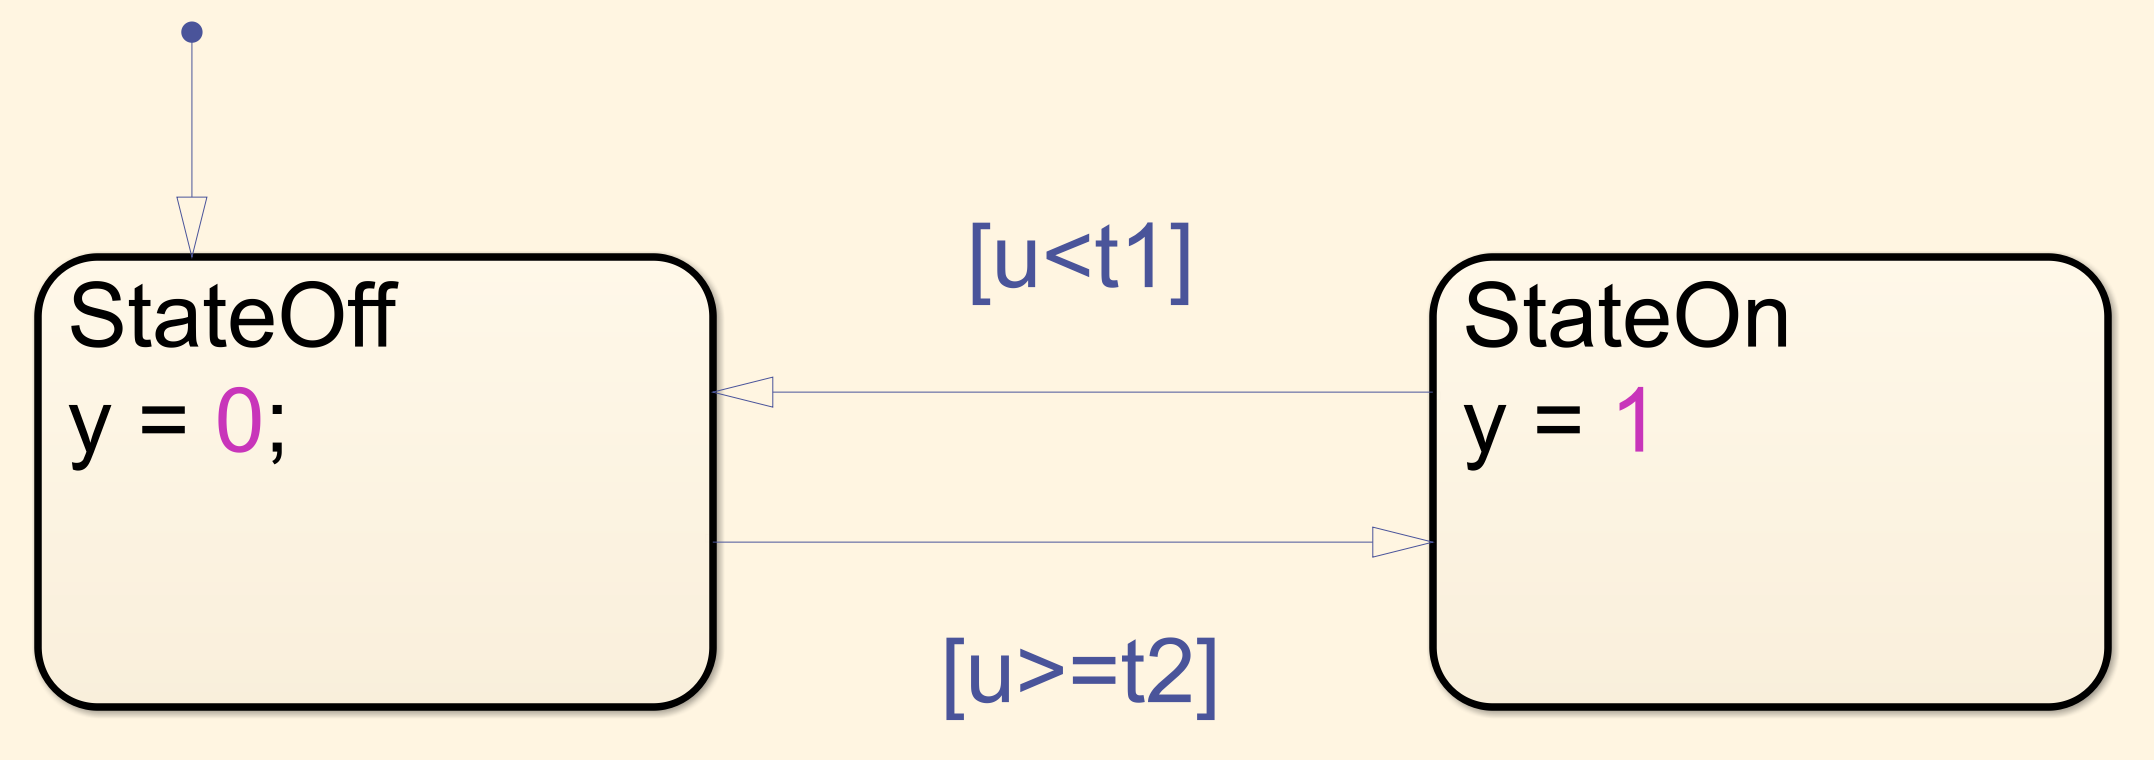

 **Exercise. **Based on the Stateflow chart above, identify the corresponding control algorithm used.

IdentifyControlStateflow("None",...
"None",...
"None");
 

In the rest of this script, we will develop and deploy the hysteresis control algorithm.

 **Exercise.** Open the Stateflow chart (double-click) and create the initial state. In this state, the fan should be off and so the FanSpeed is set to 0.

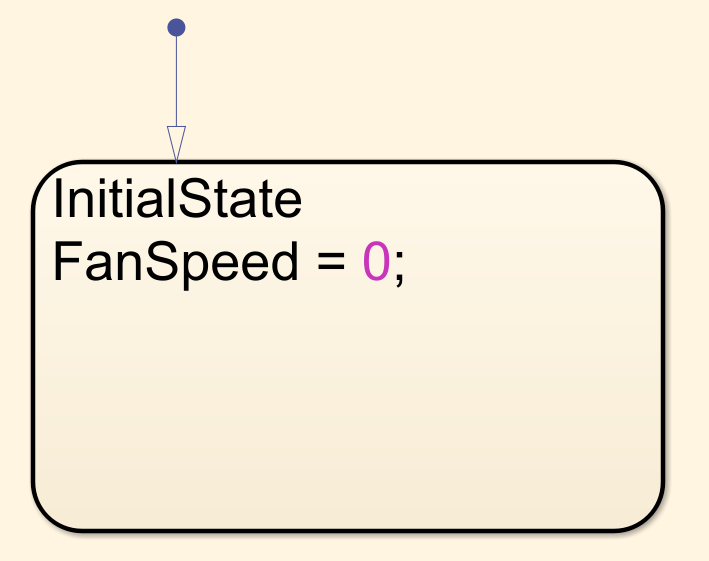

 CheckInitialState;

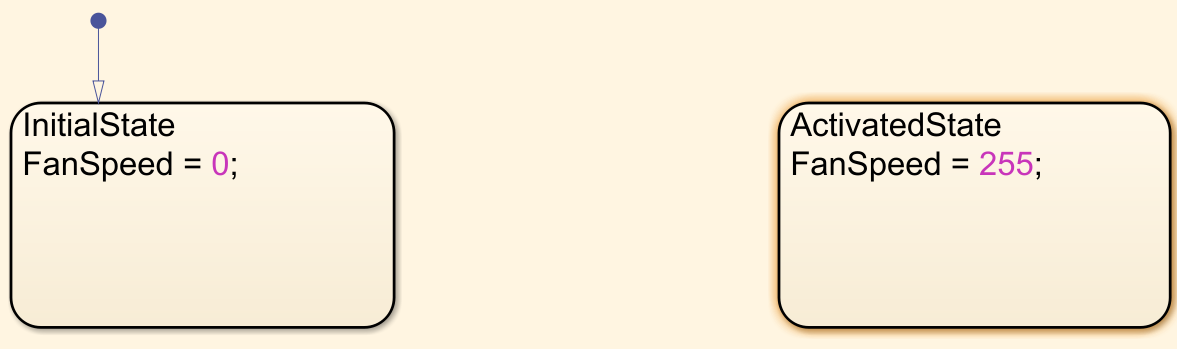

 **Exercise.** Create a second state, when the fan should be on. The PWM signal value is controlled by a value from 0 to 255. We have varying speed fan, so the FanSpeed can be set to maximum speed of 255 in this state.

  CheckActivatedState;

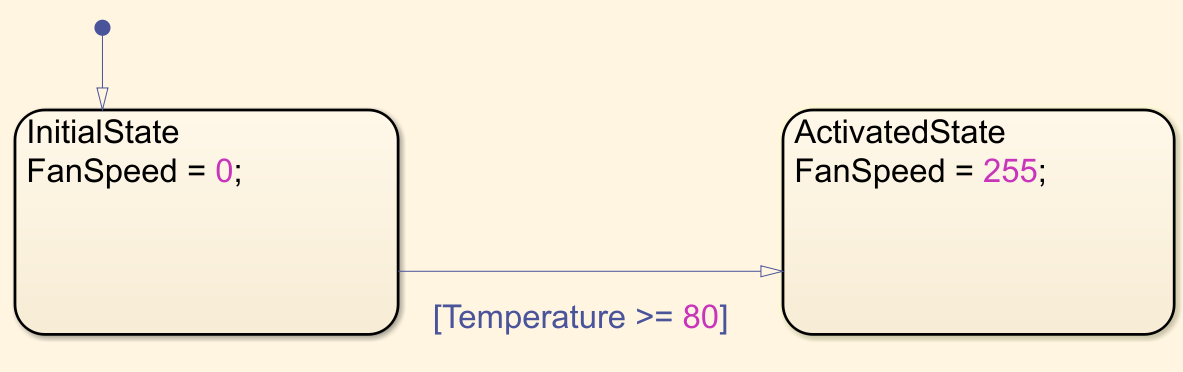

 **Exercise.** Create a first transition from InitialState to the ActivatedState when the Temperature goes above 80 F

  CheckFirstTransition;

 **Exercise.** Create a second transition from ActivatedState to the InitialState when the Temperature goes below 75 F

  CheckSecondTransition;

  **Try. **Now that the hysteresis control is implemented, deploy the algorithm to see if the fan is on or off (how warm is it in the room?)

## Further exploration

Now that you have created a control algorithm for the fan, we have more to explore to make this ventilation solution complete:

- We can validate the size of the fan using a model in [GreenhouseModel.mlx](matlab:open('./GreenhouseModel.mlx'))

- We can connect the Arduino to send an alert if the temperature becomes too high in [ConnectedGreenhouse.mlx](matlab:open('./ConnectedGreenhouse.mlx'))

[⇦ Return to the main menu](matlab:open('../MainMenu.mlx'))

## Helper Functions

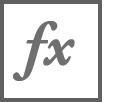`CheckDHTBlock`

function CheckDHTBlock(MyDHTPin)

bl = getfullname(Simulink.findBlocks('GreenhouseControl'));

isBlock = find(contains(bl,'GreenhouseControl/DHT')); %#ok<EFIND>

if ~isempty(isBlock)
    try
        myDHTUnit = string(get_param('GreenhouseControl/DHT','F'));
        myDHTPin = string(get_param('GreenhouseControl/DHT','Pin'));
        myDHTSensorType = string(get_param('GreenhouseControl/DHT','Tp'));
        myDHTSampleTime = string(get_param('GreenhouseControl/DHT','Ts'));
        
        myAnswers = [myDHTUnit, myDHTPin, myDHTSensorType, myDHTSampleTime];

        answer = ["on", MyDHTPin,"11","0.5"];

        if ~all(myAnswers==answer)
            if myAnswers(1)~= answer(1)
                warning("Please check that you have input the correct parameter for temperature unit.")
            end
            if myAnswers(2)~= answer(2)
                warning("Please check that you have input the correct parameter for Pin.")
            end
            if myAnswers(3)~= answer(3)
                warning("Please check that you have input the correct parameter for Sensor Type.")
            end
            if myAnswers(4)~= answer(4)
                warning("Please check that you have input the correct parameter for Sample Time.")
            end
               
        else
            disp("Good job! You have correctly added the block and assigned the parameters in the Simulink model.")
        end
    catch
    end
else
    warning("Please check that you have inserted a DHT block into your model.")
end
end

`CheckDCFanBlock`

function CheckDCFanBlock(MyFanPin)

bl = getfullname(Simulink.findBlocks('GreenhouseControl'));

isBlock = find(contains(bl,'GreenhouseControl/PWM')); %#ok<EFIND>

if ~isempty(isBlock)
    try
        myDCFanPin = string(get_param('GreenhouseControl/PWM','pinNumber'));
        myDCFanFreqType = string(get_param('GreenhouseControl/PWM','frequencyType'));
        myAnswers = [myDCFanPin, myDCFanFreqType];
        answer = [MyFanPin,"Default"];

        if ~all(myAnswers==answer)
            if myAnswers(1) ~= answer(1)
                warning("Please check that you have the right pin number.")
            end
            if myAnswers(2) ~= answer(2)
                warning("Please check that the frequency type is set to default.")
            end               
        else
            disp("Good job! You have correctly added the block and assigned the parameters in the Simulink model.")
        end
    catch
    end
else
    warning("Please check that you have inserted a PWM block named DC Fan into your model.")
end
end

`CheckInsertChart`

function CheckInsertChart

    bl = getfullname(Simulink.findBlocks('GreenhouseControl'));
    
    isBlock = find(contains(bl,'GreenhouseControl/Chart'));
    
    if ~isempty(isBlock)
        disp("Good job! You inserted the chart correctly.")
    else
        warning("Please insert a stateflow chart and make sure it is called 'Chart'")
    end
end


`ConnectectTo`

function y = ConnectectTo(modelname,srcBlockName,dstBlockName)
    Connectivities = get_param(modelname+"/"+srcBlockName,'PortConnectivity');
    y = false;
    for i = 1:length(Connectivities)
        name = string(get_param(Connectivities(i).DstBlock,"Name"));
        if any(name == dstBlockName)
            y = true;
        end
    end
end

`CheckConnectionPWM`

function CheckConnectionPWM
    load_system(fullfile("Models","GreenhouseControl.slx"));
    bl = getfullname(Simulink.findBlocks('GreenhouseControl'));
    isBlock = find(contains(bl,'GreenhouseControl/Chart'));
    if isempty(isBlock)
        warning("There is no Chart inserted in the model.")
    else
        InputName = find(sfroot,'-isa','Stateflow.Data',Path='GreenhouseControl/Chart',Scope='Output');
        InputName = string(InputName.Name);
        if  ~strcmpi(InputName,"FanSpeed")
            warning("Rename the inport to 'FanSpeed' before continuing.")
        else
            disp("Good job! You connected your Stateflow chart to the Fan correctly.")
        end
    end
end

`CheckConnectionDHT`

function CheckConnectionDHT
    load_system(fullfile("Models","GreenhouseControl.slx"));
    bl = getfullname(Simulink.findBlocks('GreenhouseControl'));
    isBlock = find(contains(bl,'GreenhouseControl/Chart'));
    if isempty(isBlock)
        warning("There is no Chart inserted in the model.")
    else
        InputName = find(sfroot,'-isa','Stateflow.Data',Path='GreenhouseControl/Chart',Scope='Input');
        InputName = string(InputName.Name);
        if  ~strcmpi(InputName,"Temperature")
            warning("Rename the inport to 'Temperature' before continuing.")
        else
            disp("Good job! You connected your Stateflow chart to the DHT correctly.")
        end
    end
end


`IdentifyControlSignal`

function IdentifyControlSignal(TopSignal,MiddleSignal,BottomSignal)

    err = false;
    if TopSignal ~= "Hysteresis + Debouncing"
        warning("You have identified the top signal wrong, try again!")
        err = true;
    end
    if MiddleSignal ~= "Hysteresis"
        warning("You have identified the middle signal wrong, try again!")
        err = true;
    end
    if BottomSignal ~= "Simple Treshold"
        warning("You have identified the bottom signal wrong, try again!")
        err = true;
    end
    if ~err
        disp("Good job! You have identified the signals correctly.")
    end
end

`CheckInitialState`

function CheckInitialState

    erri = false;
    load_system(fullfile("Models","GreenhouseControl.slx"));
    bl = getfullname(Simulink.findBlocks('GreenhouseControl'));
    isBlock = find(contains(bl,'GreenhouseControl/Chart')); %#ok<*EFIND>
    if isempty(isBlock)
        warning("There is no Chart inserted in the model.")
        erri = true;
    end

    if ~erri
        err = false;
        s=sfroot;
        states = find(s,'-isa','Stateflow.State');
        if any(string(get(states,"Name")) == "InitialState")
            states = states(string(get(states,"Name")) == "InitialState");
        else
            warning("The initial state should be called 'InitialState'.")
            err = true;
        end
        label = split(string(get(states,"LabelString")),newline);
        if ~any(contains(label,"FanSpeed"))
            err = true;
            warning("You need to specify the FanSpeed at the initial state.")
        else
            label = label(contains(label,"FanSpeed"));
            labelvalue = extractAfter(label,"=");
            if contains(labelvalue,";")
                labelvalue = extractBefore(labelvalue,";");
            end
            if strtrim(labelvalue) ~= "0"
                err = true;
                warning("The fan speed should be set to 0.")
            end
        end
        
        if ~err
            disp("Good job! You defined the inital state correctly.")
        end
    end
end

`CheckActivatedState`

function CheckActivatedState
    erri = false;
    load_system(fullfile("Models","GreenhouseControl.slx"));
    bl = getfullname(Simulink.findBlocks('GreenhouseControl'));
    isBlock = find(contains(bl,'GreenhouseControl/Chart'));
    if isempty(isBlock)
        warning("There is no Chart inserted in the model.")
        erri = true;
    end

    if ~erri
        err = false;
        s=sfroot;
        states = find(s,'-isa','Stateflow.State');
        names = [];
        for i = 1:size(states,1)
            names = [names; string(states(i).Name)]; %#ok<AGROW>
        end
        if ~any(names == "ActivatedState")
            warning("The second state should be called 'InitialState'.")
            err = true;
        else
            states = states(names == "ActivatedState");
        end
        label = split(string(get(states,"LabelString")),newline);
        if ~any(contains(label,"FanSpeed"))
            err = true;
            warning("You need to specify the FanSpeed at the activated state.")
        else
            label = label(contains(label,"FanSpeed"));
            labelvalue = extractAfter(label,"=");
            if contains(labelvalue,";")
                labelvalue = extractBefore(labelvalue,";");
            end
            if strtrim(labelvalue) ~= "255"
                err = true;
                warning("The fan speed should be set to 255.")
            end
        end
    
        if ~err
            disp("Good job! You defined the activated state correcty.")
        end
    end
end

`CheckFirstTransition`

function CheckFirstTransition
    erri = false;
    load_system(fullfile("Models","GreenhouseControl.slx"));
    bl = getfullname(Simulink.findBlocks('GreenhouseControl'));
    isBlock = find(contains(bl,'GreenhouseControl/Chart'));
    if isempty(isBlock)
        warning("There is no Chart inserted in the model.")
        erri = true;
    end

    if ~erri
        err = false;
        err2 = true;
        s=sfroot;
        transition = find(s,'-isa','Stateflow.Transition');
        clear s 
        for i = 1:size(transition,1)
            src = string(get(transition(i).Source,'Name'));
            if isempty(src)
                src = "";
            end
            dst = string(get(transition(i).Destination,'Name'));
            if isempty(dst)
                dst = "";
            end
            if src == "InitialState" & dst == "ActivatedState"
                err2 = false;
                label = string(transition(i).LabelString);
            end
        end
        
        if ~err2
            label = replace(label," ","");
            if label ~= "[Temperature>=80]"
                err = true;
                warning("The transition condition is wrong.")
            end
        else
            warning("The transition from Initial State to Activated State does not exist.")
        end
        
        if ~err & ~err2
            disp("Good job! The first transition was created correctly.")
        end
    end
end

`CheckSecondTransition`

function CheckSecondTransition
    erri = false;
    load_system(fullfile("Models","GreenhouseControl.slx"));
    bl = getfullname(Simulink.findBlocks('GreenhouseControl'));
    isBlock = find(contains(bl,'GreenhouseControl/Chart'));
    if isempty(isBlock)
        warning("There is no Chart inserted in the model.")
        erri = true;
    end

    if ~erri
        err = false;
        err2 = true;
        s=sfroot;
        transition = find(s,'-isa','Stateflow.Transition');
        clear s 
        for i = 1:size(transition,1)
            src = string(get(transition(i).Source,'Name'));
            if isempty(src)
                src = "";
            end
            dst = string(get(transition(i).Destination,'Name'));
            if isempty(dst)
                dst = "";
            end
            if src == "ActivatedState" & dst == "InitialState"
                err2 = false;
                label = string(transition(i).LabelString);
            end
        end
        
        if ~err2
            label = replace(label," ","");
            if label ~= "[Temperature<75]"
                err = true;
                warning("The transition condition is wrong.")
            end
        else
            warning("The transition from Activated State to Initial State does not exist.")
        end
        
        if ~err & ~err2
            disp("Good job! The second transition was created correctly.")
        end
    end
end

`IdentifyControlStateflow`

function IdentifyControlStateflow(treshold,hyst,hystDebc)
    err = false;
    if treshold ~= "A"
        warning("You picked the wrong Stateflow for the simple threshold")
        err = true;
    end
    if hyst ~= "C"
        warning("You picked the wrong Stateflow for the Hysteresis.")
        err = true;
    end
    if hystDebc ~= "B"
        warning("You picked the wrong Stateflow for the Hysteresis with Debouncing.")
        err = true;
    end
    if ~err
        disp("Good job! You have identified the Stateflow charts correctly.")
    end
end

[⇦ Return to the main menu](matlab:open('../MainMenu.mlx'))

Copyright 2023 The MathWorks™, Inc